# Gasoline Price Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

countries = readmatrix("./data/gaspriceData.xlsx", "Sheet", "countries", "OutputType", "string");
pricesRaw = readmatrix("./data/gaspriceData.xlsx", "Sheet", "pricesRaw");
yrRaw = readmatrix("./data/gaspriceData.xlsx", "Sheet", "yrRaw");
whos

  Name            Size            Bytes  Class     Attributes

  countries       1x10              668  string              
  pricesRaw      19x10             1520  double              
  yrRaw          19x1               152  double              



## Task 1

Gasoline price data is imported from the file `gaspriceData.mat`, which contains the following variables:

- `pricesRaw`: a 19-by-10 matrix of gasoline prices from 10 countries for the years 1990-2008

- `yrRaw`: a column vector of the years 1990-2008

- `countries`: a cell array of text containing the countries whose data is in the corresponding columns of `pricesRaw`

[https://www.eia.doe.gov](https://www.eia.doe.gov/)

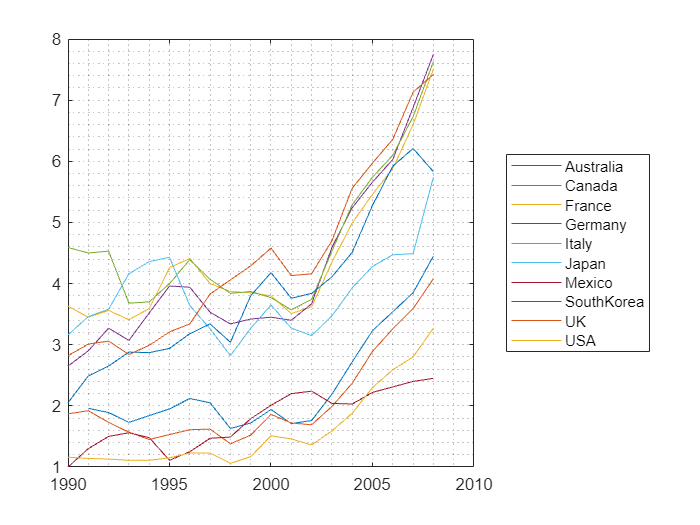

plot(yrRaw, pricesRaw)
grid minor
legend(countries, "Location", "eastoutside")

## Task 2

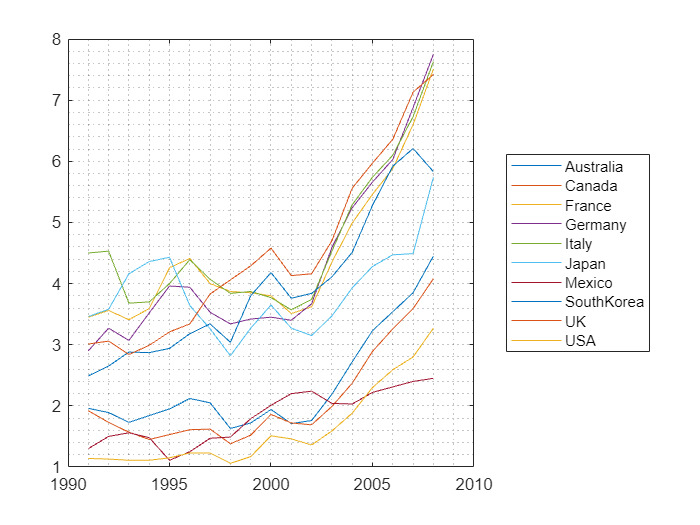

[prices, badRows] = rmmissing(pricesRaw);
yr = yrRaw(~badRows);
plot(yr, prices)
grid minor
legend(countries, "Location", "eastoutside")

## Task 3

The `normalize` function will normalize data such that it has a mean of 0 and a standard deviation of 1.

`d` `=` `normalize``(``d``)`

Because `normalize` is a statistical function, it acts on the columns of a matrix independently.

pricesNorm = normalize(prices)

pricesNorm =    -0.4597   -0.2215   -0.8444   -0.9990   -0.1262   -0.5694   -1.2101   -1.2239   -1.0172   -0.7064
   -0.5425   -0.4568   -0.7516   -0.7373   -0.1008   -0.3974   -0.7491   -1.0884   -0.9826   -0.7212
   -0.7316   -0.6549   -0.8781   -0.8787   -0.8213    0.4340   -0.6108   -0.8936   -1.1348   -0.7509
   -0.6016   -0.8035   -0.7263   -0.5604   -0.8043    0.7207   -0.7952   -0.9020   -1.0310   -0.7509
   -0.4715   -0.7044   -0.1612   -0.2492   -0.5500    0.8210   -1.6481   -0.8428   -0.8788   -0.6915
   -0.2706   -0.6053   -0.0347   -0.2633   -0.2194   -0.3114   -1.3254   -0.6395   -0.7888   -0.5728
   -0.3533   -0.5930   -0.3805   -0.5533   -0.4907   -0.8560   -0.8183   -0.5040   -0.4498   -0.5728
   -0.8498   -0.8901   -0.4901   -0.6877   -0.6856   -1.4867   -0.7722   -0.7581   -0.2906   -0.8250
   -0.7434   -0.7168   -0.5070   -0.6312   -0.6602   -0.8417   -0.0807   -0.1143   -0.1315   -0.6618
   -0.4834   -0.2958   -0.5492   -0.6099   -0.7450   -0.2970    0.4264    0.20

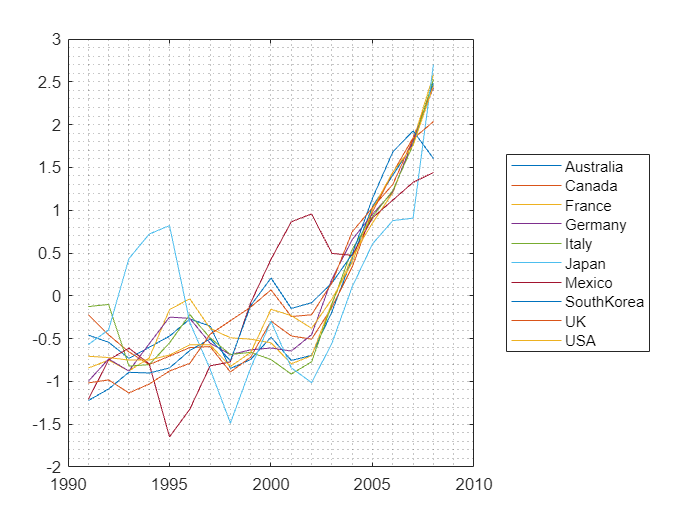

plot(yr, pricesNorm)
grid minor
legend(countries, "Location", "eastoutside")